# **Digital Communications TTT4130 - Matlab Lab Sessions**

**Lab Responsible**: Johan Suarez (johan.suarez@ntnu.no)

`Prerequisites`

Up-to-date installation of `MATLAB `and `SIMULINK `including `Communications Toolbox. (NTNU students receive Campus license)`

`Instructions`

**All lab sessions are group projects. Groups will be assigned randomly and consist of 2-3 people.** 

This is a Matlab live script. The script will guide through the lab session with coding tasks accompanied by explanations and comments.

**Please download and install MATLAB/Simulink and include the Communications toolbox as add-in. **

**You are free to use any resource you think is useful. Collaboration and discussion between groups is encouraged. **

# `Project 3 - Channel Coding`

### `Digital Communication System Schematic`

# 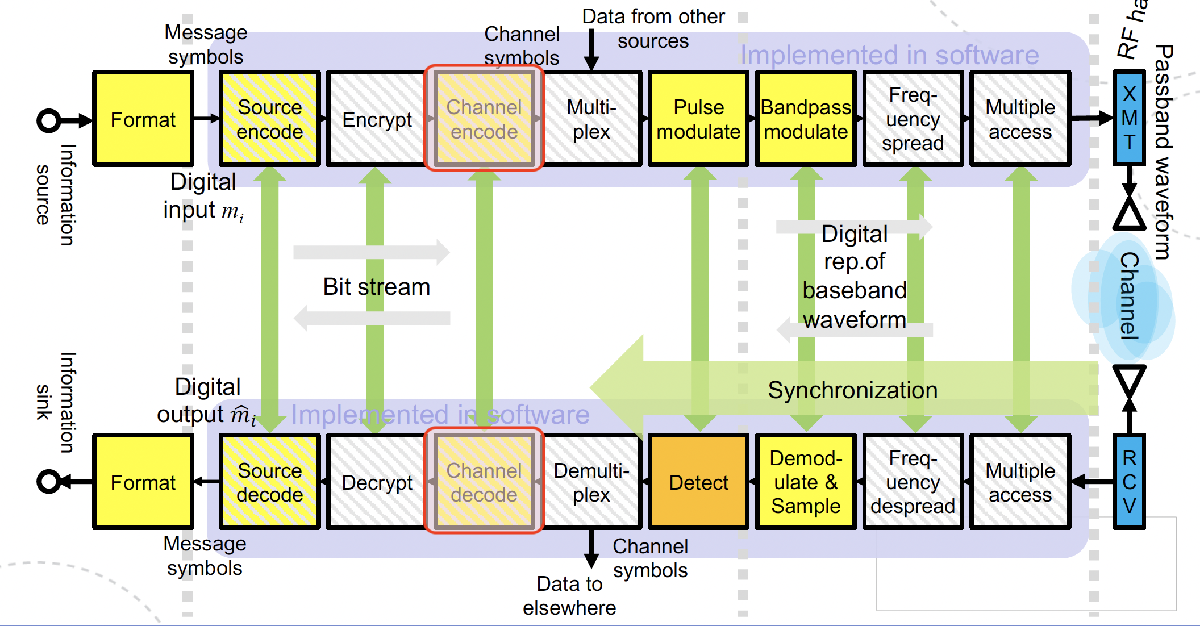

Specifically, the lab session covers the highlighted (red) parts of the schematic depicted above. 

### `Course Content`

- Coding Gain

- Convolutional Codes

- Cyclic redundancy check

- Bit interleaved coded modulation

#### `Task 1 : Hamming Code`

This task illustrates the principle of *block codes*. 

- Generator Matrix

- Parity Check Matrix

- Syndrome

Recomended reading: Section 6.4 *Linear Block Codes *in *Digital Communications, Sklar*

% Tip: Use MatLab inbuilt functions whenever possible 


% Define message length k and codeword length n 
n = 7; k = 4;     

% Generate random binary message of length k
m = randi([0,1], 1, k);
m

m =      1     1     1     1




% Generate parity check matrix and generator matrix using hammgen()
[h,g] = hammgen(3);
h

h =      1     0     0     1     0     1     1
     0     1     0     1     1     1     0
     0     0     1     0     1     1     1


g

g =      1     1     0     1     0     0     0
     0     1     1     0     1     0     0
     1     1     1     0     0     1     0
     1     0     1     0     0     0     1



% Encode the message using encode()
em  = encode(m,n,k);
em, m

em =      1     1     1     1     1     1     1


m =      1     1     1     1


%  Use the first column of the codes STANDARD ARRAY to construct the error
%  pattern -> syndrome LUT

%  creating error message
errors = eye(n);
errors, em

errors =      1     0     0     0     0     0     0
     0     1     0     0     0     0     0
     0     0     1     0     0     0     0
     0     0     0     1     0     0     0
     0     0     0     0     1     0     0
     0     0     0     0     0     1     0
     0     0     0     0     0     0     1


em =      1     1     1     1     1     1     1


erroredMessage = mod(em + errors(:,1)',2);% bitflip
erroredMessage

erroredMessage =      0     1     1     1     1     1     1


syndrome = mod(h * erroredMessage',2);
syndrome, erroredMessage, h

syndrome =      1
     0
     0


erroredMessage =      0     1     1     1     1     1     1


h =      1     0     0     1     0     1     1
     0     1     0     1     1     1     0
     0     0     1     0     1     1     1



% Introduce 1-bit errors at different positions in the codeword and calculate the
% syndrome of the error

% making matrix with one error on every index
% Flip 1 bit
errorAtAllPos = mod(errors + em,2);
syndromes = mod(h * errorAtAllPos',2);

% Decode using created LUT & check if 1-bit error can be successfully
% decoded
h,syndromes(:,2)

h =      1     0     0     1     0     1     1
     0     1     0     1     1     1     0
     0     0     1     0     1     1     1


ans =      0
     1
     0


%Usig the LUT
[~, idx] = ismember(syndromes', h', "rows");
errorAtAllPos,em, idx

errorAtAllPos =      0     1     1     1     1     1     1
     1     0     1     1     1     1     1
     1     1     0     1     1     1     1
     1     1     1     0     1     1     1
     1     1     1     1     0     1     1
     1     1     1     1     1     0     1
     1     1     1     1     1     1     0


em =      1     1     1     1     1     1     1


idx =      1
     2
     3
     4
     5
     6
     7


for i = 1:n
    errorAtAllPos(i,idx(i)) = mod(errorAtAllPos(i,idx(i)) + 1,2);
end
errorAtAllPos, em

errorAtAllPos =      1     1     1     1     1     1     1
     1     1     1     1     1     1     1
     1     1     1     1     1     1     1
     1     1     1     1     1     1     1
     1     1     1     1     1     1     1
     1     1     1     1     1     1     1
     1     1     1     1     1     1     1


em =      1     1     1     1     1     1     1




% ------------------------------------------------- %

% Flip 2 bits at different positions and check if the erraneous codeword
% can be successfully decoded
bits_to_flip = [0,0,0,0,1,1,0]; 
two_bitflips = mod(em + bits_to_flip,2);
em, two_bitflips

em =      1     1     1     1     1     1     1


two_bitflips =      1     1     1     1     0     0     1


syndrome_two = mod(h * two_bitflips',2);
syndrome_two

syndrome_two =      1
     0
     0



% Decode with Matlab inbuilt functions and confirm your findings from above
[~, idx] = ismember(syndrome_two', h', "rows");
em, two_bitflips, syndrome_two, h, idx

em =      1     1     1     1     1     1     1


two_bitflips =      1     1     1     1     0     0     1


syndrome_two =      1
     0
     0


h =      1     0     0     1     0     1     1
     0     1     0     1     1     1     0
     0     0     1     0     1     1     1


idx = 1

#### `Task 2 : Convolutional Encoder & Decoder`

- Convolutional Encoding

- Convolutional Code Parameters

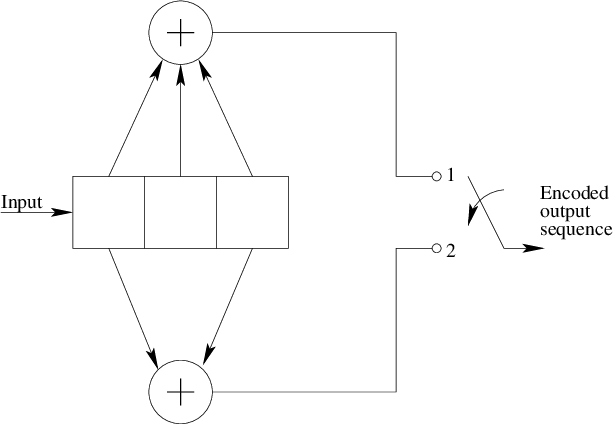    

Determine the convolutional coding parameters from the schematic above. Then implement the convolutional encoder for a binary sequence of your choice. 

If you decide to use a non continous message bit stream (i.e., a message of specific length) *flush *the registers. 

*(refer to p. 378ff Digital Communcations, Sklar)*

% Implement the Convolutional Decoder and encode a binary message
message_len = 10;
m = randi([0,1], 1, message_len);
m_copy = m;
moders = [1 1 1; 1 0 1]';%taken from drawing
em = [];
state = [0,0];

for i = 1:message_len
    word = [m_copy(i) state];
    sm = mod(sum(and(moders', word),2),2);% sum of adder mod 2
    em = cat(1,em, sm');
    %shift reg

    state = word(1:2);
end
em

em =      1     1
     1     0
     0     0
     1     0
     1     1
     1     1
     0     1
     0     1
     0     0
     1     0



% Encode using the built-in convolutional encoder for comparison
%doing matlabs method
trell = poly2trellis(3, [7, 5]); 

tmp = convenc(m_copy, trell);
out = reshape(tmp, 2, [])';   % <-- transpose after reshape
%display
m_copy,em, out

m_copy =      1     0     1     0     0     1     1     0     1     0


em =      1     1
     1     0
     0     0
     1     0
     1     1
     1     1
     0     1
     0     1
     0     0
     1     0


out =      1     1
     1     0
     0     0
     1     0
     1     1
     1     1
     0     1
     0     1
     0     0
     1     0


% Encode using the built-in convolutional encoder for comparison
function CONV_enc_m = conv_encode(m)
    % Define trellis (g1 = 111, g2 = 101)
    trellis = poly2trellis(3, [7 5]);

    % Encode message
    CONV_enc_m = convenc(m, trellis);
end

#### `Task 3 : Cyclic Redundancy Check - CRC`

Now use a CRC encoder on your message.

Obtain an estimate for the error detection capability of the CRC, i.e. what is the probability of missed error detection of the CRC, and the overhead introduced.

% Original message
m = randi([0,1], 1, k);
% CRC encode
CRC_gen = comm.CRCGenerator([1, 0, 0, 1, 1]);

CRC_enc_m = CRC_gen(m');
CRC_enc_m

CRC_enc_m =      0
     1
     1
     1
     1
     0
     0
     1


% Convolutional encode (Task 2 function, or matlab built-in function)
CONV_enc_m = conv_encode(CRC_enc_m);
CONV_enc_m

CONV_enc_m =      0
     0
     1
     1
     0
     1
     1
     0
     1
     0
     0
     1
     1
     1
     1


% Simulate channel — introduce errors
received_m = CONV_enc_m;
errors = [0 0 0 0 0 0 0 1 0 0 0 0 0 0 0 0]';
errors

errors =      0
     0
     0
     0
     0
     0
     0
     1
     0
     0
     0
     0
     0
     0
     0


received_m = mod(received_m + errors, 2); % XOR
received_m

received_m =      0
     0
     1
     1
     0
     1
     1
     1
     1
     0
     0
     1
     1
     1
     1


% Viterbi decode
tbdepth = 5;
trellis = poly2trellis(3, [7 5]);
decoded_m = vitdec(received_m, trellis, tbdepth, 'trunc', 'hard');
decoded_m

decoded_m =      0
     1
     1
     1
     1
     0
     0
     1


% CRC check — did Viterbi recover everything correctly?
CRC_det = comm.CRCDetector([1, 0, 0, 1, 1]);
[decoded_data, err] = CRC_det(decoded_m);
err

err = 0

N = 10000;
P_B = 0.1;

tot_errors = 0;
missed_errors = 0;

for i = 1:N
    msg = randi([0 1], 1, k); % Generate msg
    
    % Encode
    CRC_enc_msg = CRC_gen(msg'); % CRC
    CONV_enc_msg = conv_encode(CRC_enc_msg); % CONV
    
    % Introducing errors
    errors = rand(size(CONV_enc_msg)) < P_B;
    received_msg = mod(CONV_enc_msg + errors, 2); 
    
    % Viterbi decode
    tbdepth = 5;
    decoded_msg = vitdec(received_msg, trellis, tbdepth, 'term', 'hard');

    % CRC check
    [decoded_data, err] = CRC_det(decoded_msg);
    
    % Check errors
    if any(decoded_data ~= msg')
        tot_errors = tot_errors + 1;

        if err == 0
            missed_errors = missed_errors + 1;
        end
    end

end

P_missed = missed_errors / tot_errors;

tot_errors

tot_errors = 2419

missed_errors

missed_errors = 131

fprintf('Missed detection probability: %f\n', P_missed);

Missed detection probability: 0.054155


`Task 4: Interleaving`

Realise a system that utilises convolutional coding and eventually cyclic redundancy checks to correct and detect errors in transmission.

Document the minimum separation achieved by the interleaver.

% Message + CRC
m = randi([0 1], 1, k)

m =      1     1     1     0


msg_crc = CRC_gen(m')

msg_crc =      1
     1
     1
     0
     0
     0
     0
     1




% Convolutional encoding
msg_crc_convenc = conv_encode(msg_crc)

msg_crc_convenc =      1
     1
     0
     1
     1
     0
     0
     1
     1
     1
     0
     0
     0
     0
     1




% Interleaving
% intrlvd = matintrlv(msg_crc_convenc, 4, 4)
L = length(msg_crc_convenc);

cases = [2 2; 4 4]

cases =      2     2
     4     4



for t = 1:size(cases,1)
    rows = cases(t,1);
    cols = cases(t,2);
    blockLen = rows * cols;

    fprintf('Testing %dx%d interleaver\n', rows, cols);

    % Pad so the message fits an integer number of interleaver blocks
    padLen = mod(blockLen - mod(L, blockLen), blockLen);
    if padLen == blockLen
        padLen = 0;
    end

    msg_pad = [msg_crc_convenc; zeros(padLen,1)];
    idx_pad = [(1:L)'; zeros(padLen,1)];   % track original positions

    numBlocks = length(msg_pad) / blockLen;

    intrlvd_msg = [];
    intrlvd_idx = [];

    for b = 1:numBlocks
        startIdx = (b-1)*blockLen + 1;
        stopIdx  = b*blockLen;

        block_msg = msg_pad(startIdx:stopIdx);
        block_idx = idx_pad(startIdx:stopIdx);

        intrlvd_msg = [intrlvd_msg; matintrlv(block_msg, rows, cols)];
        intrlvd_idx = [intrlvd_idx; matintrlv(block_idx, rows, cols)];
    end

    % Remove padded index markers
    intrlvd_idx = intrlvd_idx(intrlvd_idx ~= 0);

    % pos_after(i) = new position of original bit i
    pos_after = zeros(L,1);
    for i = 1:L
        pos_after(intrlvd_idx(i)) = i;
    end

    % Separation between originally adjacent bits
    sep = abs(diff(pos_after));
    minSep = min(sep);

    fprintf('Encoded length: %d\n', L);
    fprintf('Block length: %d\n', blockLen);
    fprintf('Minimum separation achieved: %d\n', minSep);
    fprintf('-----------------------------\n');
end

Testing 2x2 interleaver


Encoded length: 16


Block length: 4


Minimum separation achieved: 1


-----------------------------


Testing 4x4 interleaver


Encoded length: 16


Block length: 16


Minimum separation achieved: 4


-----------------------------




% 16-QAM modulation. Note: needs groups of 4 bits, Matlab function qammod()
msg_modulated = qammod(intrlvd_msg, 16, 'InputType', 'bit', 'UnitAveragePower',true)

msg_modulated =    0.3162 - 0.9487i
   0.9487 - 0.9487i
  -0.9487 + 0.3162i
   0.3162 + 0.3162i


% Channel — AWGN
noisy_msg = awgn(msg_modulated, 10)

noisy_msg =    0.3176 - 0.9949i
   0.8611 - 1.2923i
  -1.3289 + 0.2309i
   0.2916 - 0.0562i



% Demodulation
msg_demod = qamdemod(noisy_msg, 16, 'OutputType', 'bit', 'UnitAveragePower',true)

msg_demod =      1
     1
     1
     0
     1
     0
     1
     0
     0
     0
     0
     1
     1
     1
     1




% De-interleaving
msg_deintrlvd = matintrlv(msg_demod, 4, 4)

msg_deintrlvd =      1
     1
     0
     1
     1
     0
     0
     1
     1
     1
     0
     1
     0
     0
     1




% Viterbi decoding
decoded_msg = vitdec(msg_deintrlvd, trellis, tbdepth, 'trunc', 'hard')

decoded_msg =      1
     1
     1
     0
     0
     0
     0
     1



% CRC check
[decoded_data, err] = CRC_det(decoded_msg);
err

err = 0

decoded_data

decoded_data =      1
     1
     1
     0


N = 10000;

tot_errors = 0;
total_bits = 0;
SNR = 5;

for i = 1:N
    m = randi([0 1], 1, k);
    
    % Encode
    msg_crc = CRC_gen(m');
    msg_crc_convenc = conv_encode(msg_crc);
    
    % Interleave
    intrlvd_msg = matintrlv(msg_crc_convenc, 4, 4);

    % Modulate
    msg_modulated = qammod(intrlvd_msg, 16, ...
        'InputType','bit','UnitAveragePower',true);

    % Channel
    noisy_msg = awgn(msg_modulated, SNR);

    % Demodulate
    msg_demod = qamdemod(noisy_msg, 16, ...
        'OutputType','bit','UnitAveragePower',true);

    % Deinterleave
    deintrlvd_msg = matdeintrlv(msg_demod, 4, 4);

    % Decode
    tbdepth = 5;
    decoded_msg = vitdec(deintrlvd_msg, trellis, tbdepth, 'term', 'hard');

    % CRC
    [decoded_data, err] = CRC_det(decoded_msg);
    
    % BER
    L = min(length(decoded_data), length(m));
    m_t = m';                      % transpose first
    bit_errors = sum(decoded_data(1:L) ~= m_t(1:L));

    tot_errors = tot_errors + bit_errors;
    total_bits = total_bits + L;
end
tot_errors

tot_errors = 6585

total_bits

total_bits = 40000

BER = tot_errors / total_bits

BER = 0.1646

BER_percentage = BER*100

BER_percentage = 16.4625

Check BER at 10dB, and 5dB

#### `Task 5: Coding Gain`

Compare the BER vs SNR performance of     

- Hamming codes

- Convolutional codes w/ hard-, and soft decoding

This is an unguided exercises. It is recommended to use Matlab inbuilt functions wherever possible. 

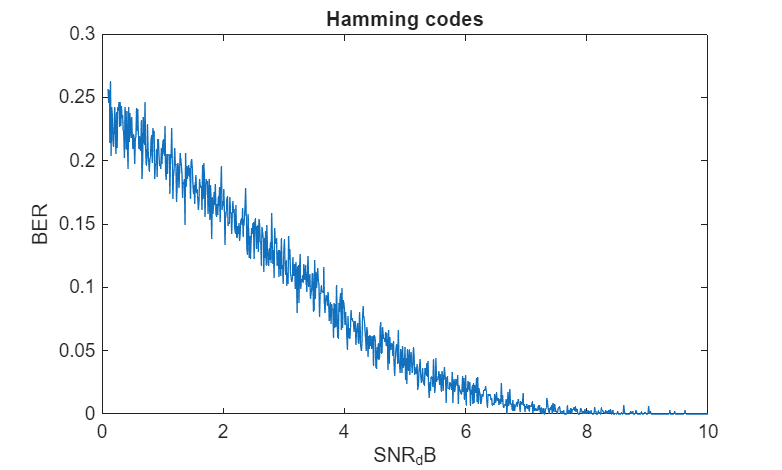

% Implementation
% Implementation
%create message

function noise_sig = add_noise(modulated_message, SNR_dB)
    SNR_lin = 10^(SNR_dB/10);
    signal_power = mean(abs(modulated_message).^2);
    noise_power = signal_power / SNR_lin;
    noise = sqrt(noise_power/2) * (randn(size(modulated_message)) + 1j*randn(size(modulated_message)));

    % Add noise to signal
    noise_sig = modulated_message + noise;
end

    %hamming
function enc = hamming_enc(message)
    n = 15;
    k = 11;
    [h,g] = hammgen(4);

    em  = encode(message,n,k);
    enc = em;
end

function dec = hamming_dec(encoded_message)
    n = 15;
    k = 11;
    msg = decode(encoded_message,n,k);
    dec = msg;
end

%convolutional
function enc = conv_enc(message)
    trell = poly2trellis(7, [171 133]);  % octal
    tmp = convenc(message, trell);
    enc = tmp;
end

function dec = conv_dec(enc_msg)
    trell = poly2trellis(7, [171 133]);
    tblen = 5 * 7;  % traceback length (rule of thumb: 5×constraint length)
    dec = vitdec(enc_msg, trell, tblen, 'trunc', 'hard');
end




message_len = 1024;%long message
hamming_m = randi([0,1], 1, message_len);
copy_hamming_m = hamming_m;

conv_m = randi([0,1], 1, message_len);
copy_conv_m = conv_m;

ham_bit_errors_local = 0;
ham_bit_errors = [];
conv_bit_errors_local = 0;

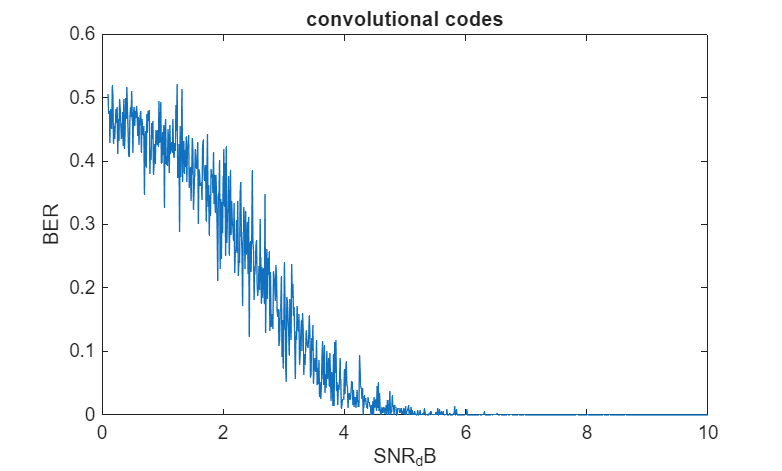

conv_bit_errors = [];

SNR_X = 0.1:0.01:10;
for SNR = SNR_X % creates vector ranging from 0.5 to 5 with 0.01 spacing
    %hamming

    hamming_em = hamming_enc(hamming_m);
    ham_mod = qammod(hamming_em,4);%modulate
    ham_mod = add_noise(ham_mod, SNR);%add noise (channel)
    ham_dmod = logical(qamdemod(ham_mod,4));%demodulate after channel
    hamming_dm = hamming_dec(ham_dmod);%decode the demodulated signal
    
    %conv
    conv_em = conv_enc(conv_m);
    conv_mod = qammod(conv_em,4);
    conv_mod = add_noise(conv_mod,SNR);
    conv_dmod = logical(qamdemod(conv_mod,4));
    conv_dm = conv_dec(conv_dmod);

    for i = 1:message_len
        %check hamming
        if hamming_m(i) ~= hamming_dm(i)
            ham_bit_errors_local = ham_bit_errors_local + 1;
        end
        
        %check conv
        if conv_m(i) ~= conv_dm(i)
            conv_bit_errors_local = conv_bit_errors_local + 1;
        end
    end
    %ham
    ham_bit_errors(end+1) = ham_bit_errors_local;
    ham_bit_errors_local = 0;
    
    %conv
    conv_bit_errors(end+1) = conv_bit_errors_local;
    conv_bit_errors_local = 0;

end
X_SNR = 0.1:0.01:10;
plot(X_SNR, ham_bit_errors/message_len);
title('Hamming codes');
xlabel('SNR_dB');
ylabel('BER');

plot(X_SNR, conv_bit_errors/message_len);
title('convolutional codes');
xlabel('SNR_dB');
ylabel('BER');
